# Magnetic Field of a Ellipse Projected on a Cylinder

#### Create Line

r = 1

r = 1

phi = pi/4

phi = 0.7854

offset = pi/4

offset = 0.7854

elevation = 1

elevation = 1

start = [r offset elevation]

start =     1.0000    0.7854    1.0000


f = ProjectedEllipse(start, r, phi);

figure;
plot3(f);

#### Pick an Observation Point

obs = [2*r 0 elevation]

obs =      2     0     1


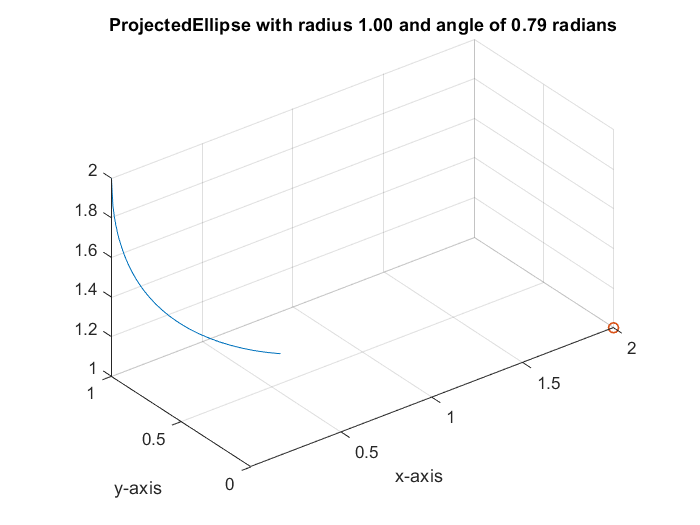


hold on;
scatter3(obs(1), obs(2), obs(3), 'LineWidth', 1);
axis equal;
hold off;

#### Calculate Magnetic Field Numerically

sample_count = 1000

sample_count = 1000


% Calculate magnetic field with specified sample count
numeric = f.observe(obs, sample_count);

#### Report Error and Configuration

disp(f)

ProjectedEllipse(radius=1.00, angle=0.79)


fprintf("Magnetic field observed at (%0.2f,%0.2f,%0.2f):", obs(1), obs(2), obs(3));

Magnetic field observed at (2.00,0.00,1.00):

fprintf(" -> Numerically: (%E,%E,%E) T", numeric(1), numeric(2), numeric(3));

 -> Numerically: (9.952110E-09,1.748165E-08,1.255520E-09) T